% Find all 3-element IED travling wave
clc;clear;close all; addpath z_toolbox;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
        'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
        'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
        'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
        'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
        'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
        'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
        'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
        'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
        'sub-0113', 'sub-0115'};
elecPath = 'step1_AwakeSEEG_BPfiltering_Age16Up';
load(fullfile('step4_IEDtw_polyfit_TD6d0', 'IEDtw_meth-None_TD-6d0.mat'));
% This section processes each subject's IED data to identify and analyze
% 3-channel sequences that represent traveling wave propagation patterns.
nTW3 = 0; TopTW3 = [];
for nS = 1:length(IEDtw) % Loop through all subjects
    IEDlabel = IEDtw(nS).label; % Get channel labels for current subject
    TWchanList = IEDtw(nS).travelingWaveChanList; % Get traveling wave channel sequences
    % 1. Extract all possible 3-channel sequences from longer traveling waves
    N = 0; TW3Str = {};
    for nTW = 1:length(TWchanList)
        for nC = 1:length(TWchanList{nTW})-2
            N = N + 1;
            % Create string representation of 3-channel sequence
            TW3Str{N} = [num2str(TWchanList{nTW}(nC)), ...
                ' ', num2str(TWchanList{nTW}(nC+1)), ...
                ' ', num2str(TWchanList{nTW}(nC+2))];
        end
    end
    % 2. Calculate frequency of each 3-channel sequence using tabulate function
    C = tabulate(TW3Str); % Get frequency count of all sequences
    TW3U = C(:, 1); % Unique sequences
    TW3UP = cell2mat(C(:, 2))./length(TW3Str);  % Probability of each sequence
    [TW3UP, idx] = sort(TW3UP, 'descend'); % Sort by probability (descending)
    TW3U = TW3U(idx); % Reorder sequences by probability
    % 3. Atlas name of top 10 3-element IED traveling wave
    % Load anatomical information for current subject
    load(fullfile(elecPath, subG{nS}, [subG{nS}, '_ROI-3mm_contactAnatomy.mat']));
    TW3UatlasProb = TW3UP(1:10);
     % Process top 10 sequences to identify anatomical locations
    for nTW = 1:10
        TW3UchanIdx = str2num(TW3U{nTW});
        TW3UatlasName = {}; 
        TW3UatlasType = [];
        nTW3 = nTW3 + 1;
        for m = 1:3
            TW3UchanLabel = IEDlabel{TW3UchanIdx(m)};
            a = strcmp(TW3UchanLabel, contAnat.label);
            CWS = contAnat.CWS{a==1};
            atlasJHU = contAnat.JHU{a==1};
            atlasYeo = contAnat.Yeo7_51{a==1};
            atlasASEG = contAnat.ASEG{a==1};
            if strcmp(CWS, 'Cortex')
                TW3UatlasName{m} = atlasYeo;
                TW3UatlasType(m) = 1;
            elseif strcmp(CWS, 'White')
                TW3UatlasName{m} = atlasJHU;
                TW3UatlasType(m) = 2;
            elseif strcmp(CWS, 'Subcortex')
                TW3UatlasName{m} = atlasASEG;
                TW3UatlasType(m) = 1;
            else
                TW3UatlasName{m} = 'none';
                TW3UatlasType(m) = 0;
            end
        end
        TopTW3(nTW3).atlasList = TW3UatlasName;
        TopTW3(nTW3).atlasListStr = [TW3UatlasName{1}, '_', TW3UatlasName{2}, '_' TW3UatlasName{3}];
        TopTW3(nTW3).atlasType = TW3UatlasType;
        TopTW3(nTW3).probability = TW3UatlasProb(nTW);
    end    
end
TopTW3 = struct2table(TopTW3);

## Probability of each series

% Calculate weighted probability of each anatomical pathway across population
C = tabulate(TopTW3.atlasListStr); % Frequency count of each anatomical pathway
probability = cell2mat(C(:, 2))./length(TopTW3.atlasListStr); % Normalized probability
weight = zeros(size(C, 1), 1); % Initialize weighting array
seriesLabelU = {}; seriesTypeU = [];
% Calculate weighted probabilities incorporating subject-level sequence probabilities
for n = 1:size(C, 1)
    a = strcmp(C{n, 1}, TopTW3.atlasListStr);
    idx = find(a==1);
    weight(n) = sum(TopTW3.probability(idx));
    seriesLabelU{n, 1} = TopTW3.atlasList{idx(1), 1};
    seriesLabelU{n, 2} = TopTW3.atlasList{idx(1), 2};
    seriesLabelU{n, 3} = TopTW3.atlasList{idx(1), 3};
    seriesTypeU(n, :) = TopTW3.atlasType(idx(1), :);
end
% Calculate final weighted probabilities
probability = (probability.*weight)./sum(weight);
probability = probability./sum(probability);
% remove none atlas
a = contains(C(:, 1), 'none');
probability = probability(a==0);
seriesLabelU = seriesLabelU(a==0, :);
seriesTypeU = seriesTypeU(a==0, :);
% sorting
[probability, idx] = sort(probability, 'descend');
seriesLabelUD = seriesLabelU(idx, :);
seriesTypeUD = seriesTypeU(idx, :);

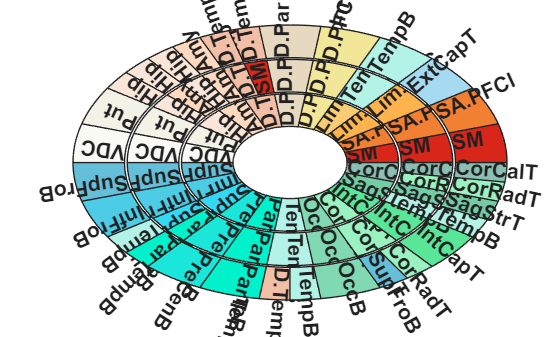

% Phylo tree color preparation - select top 30 pathways for visualization
seriesLabelUD1 = seriesLabelUD(1:30, :); % Top 30 anatomical pathways
seriesTypeUD1 = seriesTypeUD(1:30, :);   % Their tissue types
seriesLabelUD2 = seriesLabelUD1(:);
seriesTypeUD2 = seriesTypeUD1(:);
grayElements = unique(seriesLabelUD2(seriesTypeUD2==1));
whiteElements = unique(seriesLabelUD2(seriesTypeUD2==2));
% Define gray matter structures (cortical and subcortical regions)
grayElements = {'SM', 'SA.PFCl', 'Lim.OFC', 'Lim.TP', ...
            'D.PFCdm','D.Par','D.Temp', 'Amy', ...
            'Hip', 'Put', 'VDC'};
% grya matter Colormap (8×3)
grayCMap = [0.85, 0.15, 0.10;   % 1. SM (深红)
           0.95, 0.50, 0.20;   % 2. SA.PFCl (橙红)
           1.00, 0.70, 0.30;   % 3. Lim.OFC (橘黄)
           0.98, 0.80, 0.45;   % 4. Lim.TP (金黄)
           0.95, 0.90, 0.60;   % 5. D.PFCdm (浅金黄)
           0.90, 0.85, 0.75;   % 6. D.Par (米白)
           0.95, 0.75, 0.65;   % 7. D.Temp (粉橙)
           0.99, 0.85, 0.75;   % 8. Amy (粉红)
           0.98, 0.90, 0.85;   % 9. Hip (浅粉白)
           0.95, 0.95, 0.90;   % 10. Put (乳白)
           0.98, 0.98, 0.96];  % 11. VDC (极浅暖白)
whiteElements = {'SupFroB', 'InfFroB', 'SupLonF', 'PreCenB', ...
            'ParTempB', 'TempB', 'OccB', 'CorRadT', 'IntCapT', ...
            'SagStrT', 'CorCalT', 'ExtCapT'};
% white matter Colormap (8×3)
whiteCMap = [0.40, 0.75, 0.85;   % 1. SupFroB (浅蓝)
             0.30, 0.80, 0.90;   % 2. InfFroB (天蓝)
             0.20, 0.85, 0.95;   % 3. PreCenB (青蓝)
             0.10, 0.90, 0.85;   % 4. ParTemB (蓝绿)
             0.00, 0.95, 0.80;   % 5. OccipiB (青绿)
             0.70, 0.95, 0.90;   % 6. TemporB (淡青)
             0.50, 0.85, 0.70;   % 7. CorCalT (绿松石)
             0.60, 0.95, 0.75;   % 8. SupLonF (薄荷绿)
             0.35, 0.90, 0.60;   % 9. CorRadT (草绿)
             0.45, 0.80, 0.65;   % 10. ExtCapT (橄榄绿)
             0.55, 0.75, 0.70;   % 11. IntCapT (灰绿)
             0.65, 0.85, 0.95];  % 12. SagStrT (淡蓝)
% Phylotree plot
% Construct series structure
seriesStruct = f_recursiveSeriesStruct(seriesLabelUD1);
% First Element of IED traveling wave
AllElements = [grayElements, whiteElements];
ElementsColor = [grayCMap; whiteCMap];
f_phyloTree(seriesStruct, AllElements, ElementsColor, [0, 2*pi], 1);